# Gaussian External Variables

Pieter Leon van den Berg

22684166

20 Augustl 2022

Final Year Project (C) 478

Supervisor: Dr Cripwell

### Gaussian External Variables

Generate the smoothed Gaussian distribution signals to use for the external variables in the copper solvent extraction simulation

### Setup

clear;
clc;

## Simulation Time

### Simulation time

simulation_time = 700*60*60;    % [s] Run the model for 20 hours

### Fixed-step solver step size

sampling_time   = 1;         % [s] Simulate the process every 1 seconds

## Run the external variables Simulink Model

external_variables = sim('external_variables\gaussian_external_variables\gaussian_external_variables.slx');

## Read the external variables

% External variables simulation time
external_variable_time = external_variables.tout;
external_variable_time_hours = external_variable_time / (60*60);

% External variables sampled Gaussian distribution
c_PLS_training  = external_variables.c_PLS_training.Data;
c_LE_training   = external_variables.c_LE_training.Data;
f_PLSP_training = external_variables.f_PLSP_training.Data;
f_PLSS_training = external_variables.f_PLSS_training.Data;

## Plot the external variables

### Plot colours

blue   = '#06ACE9';

### Plot the external variables

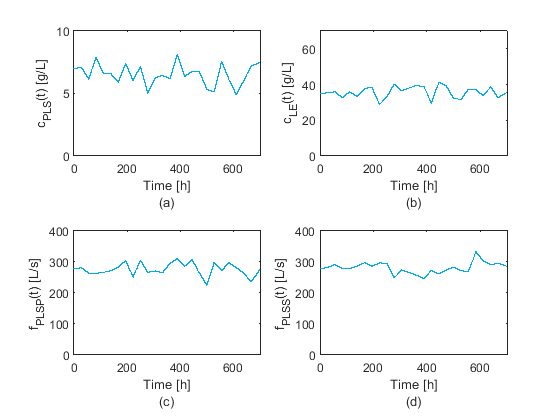

% Create the group of the external variables
figure()

% Plot c_PLS
subplot(2,2,1)
plot(external_variable_time_hours, c_PLS_training, '-', 'LineWidth', 1, 'Color', blue)
ylabel("c_{PLS}(t) [g/L]")
xlabel(["Time [h]", "(a)"])
ylim([0 10])
xlim([0 external_variable_time_hours(end)])

% Plot c_LE
subplot(2,2,2)
plot(external_variable_time_hours, c_LE_training, '-', 'LineWidth', 1,'Color', blue)
ylabel("c_{LE}(t) [g/L]")
xlabel(["Time [h]", "(b)"])
ylim([0 70])
xlim([0 external_variable_time_hours(end)])

% Plot f_PLSP
subplot(2,2,3)
plot(external_variable_time_hours, f_PLSP_training, '-', 'LineWidth', 1,'Color', blue)
ylabel("f_{PLSP}(t) [L/s]")
xlabel(["Time [h]", "(c)"])
ylim([0 400])
xlim([0 external_variable_time_hours(end)])

% Plot f_PLSS
subplot(2,2,4)
plot(external_variable_time_hours, f_PLSS_training, '-', 'LineWidth', 1, 'Color', blue)
ylabel("f_{PLSS}(t) [L/s]")
xlabel(["Time [h]", "(d)"])
ylim([0 400])
xlim([0 external_variable_time_hours(end)])

% Save the current figure
print('external_variables/output/external_variables_training', '-dpng', '-r600')